We compute SSM for an Oscillator Chain with cubic and quadratic nonlinearities as follows

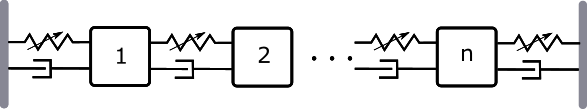

Here we focus on the transient dynamics of such a system. Specifically, the excitation is set to be zero and we calculate the response of full system and reduced systems obtained with SSM analysis.

clear all; close all; clc

## Example setup

n = 10;    % number of oscillators
mass = 1;  % mass
k = 1;     % stiffness
c = 0.1;   % damping
kappa2 = 0;   % quadratic nonlinearity
kappa3 = 0.5; % cubic nonlinearity
% kappa3 = 10; % cubic nonlinearity
% kappa3 = 0; % cubic nonlinearity

[K,C,f2,f3] = assemble_global_coefficients(k,kappa2,kappa3,c,n);

Dirichlet boundary conditions

K = K(2:n+1,2:n+1);
C = C(2:n+1,2:n+1);
M = mass*speye(n,n);
f3 = f3(2:n+1,2:n+1,2:n+1,2:n+1);

#### Dynamical System Setup

Consider the following forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}({\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}({\phi}),\\\dot{\phi}	
=\Omega$$


where 


$$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right]$$


DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',{[],f3});
set(DS.Options,'Emax',10,'Nmax',20,'notation','multiindex')
outdof = [1 2]*n/4;
outdof = [1 5];
outdof = floor(outdof);
outdof = outdof(outdof>0);
set(DS.Options, 'outDOF', outdof);

Add external forcing and also control matrix

Bext     = zeros(n,2); Bext(1,1)=1; Bext(5,2)=1;
ExtForce = @(t) Bext*[sin(0.1*sqrt(2)*t);3*cos(0.1*sqrt(3)*t)];
epsilon  = 1e-3;
set(DS,'D',Bext,'E',ExtForce,'epsilon',epsilon);

#### Linear Modal analysis

We solve generalized eigenvalue problem


$$\mathbf{A}\mathbf{V}=\mathbf{B}\mathbf{V}\mathbf{D}$$


where $\mathbf{V}=(\mathbf{v}_1,\cdots,\mathbf{v}_n)$ and $\mathbf{D}=\mathrm{diag}\{\lambda_1,\cdots,\lambda_n\}$ such that $\mathbf{A}\mathbf{v}_i=\lambda_i\mathbf{B}\mathbf{v}_i$. We also calculate the left eigenvectors $\mathbf{W}=(\mathbf{w}_1,\cdots,\mathbf{w}_n)$ such that

$\mathbf{W}^\ast\mathbf{A}=\mathbf{D}\mathbf{W}^\ast\mathbf{B}$.

The eigenvectors are normalized in the folowing way

$\mathbf{W}^\ast\mathbf{B}\mathbf{V}=\mathbb{I}$.

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 10 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.423148e-02
modal damping ratio for 2 mode is 2.817326e-02
modal damping ratio for 3 mode is 4.154150e-02
modal damping ratio for 4 mode is 5.406408e-02
modal damping ratio for 5 mode is 6.548607e-02
modal damping ratio for 6 mode is 7.557496e-02
modal damping ratio for 7 mode is 8.412535e-02
modal damping ratio for 8 mode is 9.096320e-02
modal damping ratio for 9 mode is 9.594930e-02
modal damping ratio for 10 mode is 9.898214e-02

 The first 20 nonzero eigenvalues are given as 
  -0.0041 + 0.2846i
  -0.0041 - 0.2846i
  -0.0159 + 0.5632i
  -0.0159 - 0.5632i
  -0.0345 + 0.8301i
  -0.0345 - 0.8301i
  -0.0585 + 1.0797i
  -0.0585 - 1.0797i
  -0.0858 + 1.3069i
  -0.0858 - 1.3069i
  -0.1142 + 1.5072i
  -0.1142 - 1.5072i
  -0.1415 + 1.676

## SSM Reduced dynamics - autonomous part

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
order = 3;

**Reduced dynamics simulation**

*Construction of initial condition*

% master subspace
modes = [1 2];
S.choose_E(modes);

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     1
     4     2
     5     3
     6     4
     0     2
     1     3
     2     4
     3     5
     4     6
     4     1
     5     2
     6     3
     1     4
     2     5
     3     6
These are in resonance with the follwing eigenvalues of the slave subspace
  -0.0159 + 0.5632i
  -0.0159 + 0.5632i
  -0.0159 + 0.5632i
  -0.0159 + 0.5632i
  -0.0159 + 0.5632i
  -0.0159 - 0.5632i
  -0.0159 - 0.5632i
  -0.0159 - 0.5632i
  -0.0159 - 0.5632i
  -0.0159 - 0.5632i
  -0.0345 + 0.8301i
  -0.0345 + 0.8301i
  -0.0345 + 0.8301i
  -0.0345 - 0.8301i
  -0.0345 - 0.8301i
  -0.0345 - 0.8301i
sigma_out = 48
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     1     2
     2     3
     3     4
These are in resonance with the follwing eigenvalues of the master subspace
  -0.0041 + 0.2846i
  -0.0041 + 0.2846i
  -0.0041 + 0.2846i


% compute autonomous SSM coefficients
[W_0,R_0] = S.compute_whisker(order);

Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.69E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 2.55E-02 MB


% construct initial condition
p0 = [2.5 2.5]';
% q0 = [0.8 0.8]';
z0 = reduced_to_full(p0,W_0,[],0)+0.;

% z0 = [rand(n,1)*0.1; zeros(n,1)];

## Cutoff

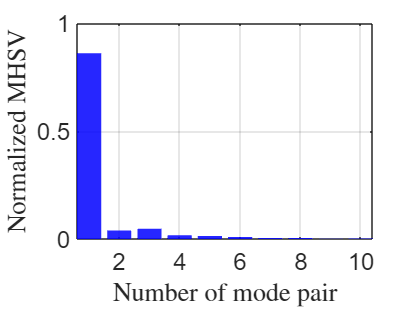

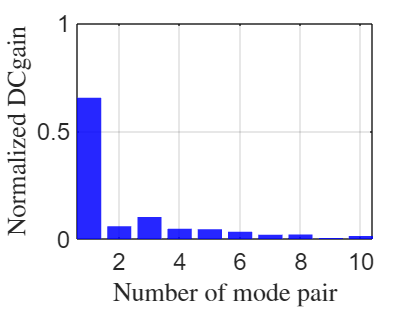

MHSV sum of the first 2 pair
    0.9000
DCgain sum of the first 2 pair
    0.7122


res = Cutof_LQR_closed_loop_MT2_comp(DS,10);

tf     = 100;
nsteps = 1000;
% tf     = 300;
% nsteps = 6000;
% for closed-loop solution, the computational time increases significantly
% when the number of grid points increases. (when interp1 is called).
% if we use griddedInterpolant, this will be ...
auData = construct_autoData(DS, modes, R_0);
tspan  = linspace(0,tf,nsteps);
% cont   = struct();
% cont.Q    = blkdiag(1e3*eye(n),zeros(n));
% cont.Rhat = 0.1*eye(2);
% cont.Mhat = 2e2*eye(2*n);
% cont.zd   = [];

cont   = struct();
cont.Q    = blkdiag(1e3*eye(n),zeros(n));
cont.Rhat = 0.05*eye(2);
cont.Mhat = 0*eye(2*n);
cont.zd   = [];

**ROM-based open loop control**

% traj_open   = LQR_open_loop(DS,z0,'nonlinear',tspan,auData,W_0,modes,1:10,cont);

**Full dynamics simulation - without control**

om = 2*pi/tf;
[tfullwo, xfullwo] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',z0);
% 
% [tfullwoL, xfullwoL] = time_integration_transient(DS,om,'nCycles',...
%     1, 'nSteps', nsteps,...
%     'integrationMethod','ode45','outdof',outdof,'init',z0);


**ROM-based closed loop control**

t0 = 0;
t1 = tf/5;
% t1 = tf;
tspan1 = linspace(t0,t1,nsteps);

% traj_closed = LQR_closed_loop(DS,z0,'nonlinear',tspan,auData,W_0,modes,1:10,cont);
traj_closed1 = LQR_closed_loop(DS,z0,'linear',tspan1,auData,W_0,modes,1:10,cont);

pl
   2.4461 - 0.0013i
   2.4461 + 0.0013i
p0
   2.4461 - 0.0013i
   2.4461 + 0.0013i
历时 0.027114 秒。
历时 0.076369 秒。
Time for backward simulation of Riccati ODE is 7.806880e-02
历时 0.234108 秒。
Time for backward simulation of compensated ODE is 2.359867e-01
历时 0.213243 秒。
Time for forward simulation of ODEs for modal coordinates is 2.349900e-01


% traj_closed = NotTT_LQR_closed_loop_MT2(DS,z0,'nonlinear',tspan,auData,W_0,modes,5,cont);

**Full dynamics simulation - with control**

om = 2*pi/t1;
ufun = @(t) transpose(interp1(traj_closed1.time,traj_closed1.ut',t));
set(DS,'u',ufun);
[tfullwc1, xfullwc1,xf,xt] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',z0);

% xf = xt(end,:);
xf  = xf';

% 
tspan2 = linspace(t1,tf,nsteps);
traj_closed2 = LQR_closed_loop(DS,xf,'linear',tspan2,auData,W_0,modes,1:10,cont);

pl
   0.5716 - 0.4713i
   0.5716 + 0.4713i
p0
   0.5716 - 0.4713i
   0.5716 + 0.4713i
历时 0.026548 秒。
历时 0.064410 秒。
Time for backward simulation of Riccati ODE is 6.611760e-02
历时 0.470547 秒。
Time for backward simulation of compensated ODE is 4.723730e-01
历时 1.115044 秒。
Time for forward simulation of ODEs for modal coordinates is 1.116840e+00


om = 2*pi/tf;
ufun = @(t) transpose(interp1(traj_closed2.time,traj_closed2.ut',t));
set(DS,'u',ufun);
[tfullwc2, xfullwc2] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',xf,'ts',t1);

#### Reduced dynamics simulation - with obtained control

% % traj2 = comp_transient_with_arbitrary_forcing(DS,z0,'nonlinear',tspan,auData,W_0,modes,1:10);

### Comparison with full dynamics - outdof 1

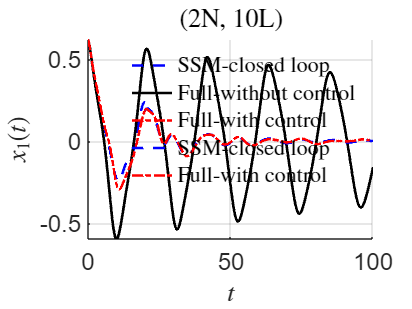

figure; hold on
% plot(traj_open.time, traj_open.zt(1,:),'b-','DisplayName','SSM-open-control');
plot(traj_closed1.time, traj_closed1.zt(1,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot(tfullwo, xfullwo(:,1),'k-','DisplayName', 'Full-without control','LineWidth',2);
plot(tfullwc1, xfullwc1(:,1),'r-.','DisplayName', 'Full-with control','LineWidth',2);

plot(traj_closed2.time, traj_closed2.zt(1,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot(tfullwc2, xfullwc2(:,1),'r-.','DisplayName', 'Full-with control','LineWidth',2);


legend('show','Interpreter',"latex"); legend boxoff
xlabel('$t$','Interpreter',"latex")
zk = strcat('$x_{',num2str(outdof(1)),'}(t)$');
ylabel(zk,'Interpreter','latex');
title('(2N, 10L)','Interpreter',"latex")
set(gca,'FontSize',18);
grid on, axis tight

### Comparison with full dynamics - outdof 2

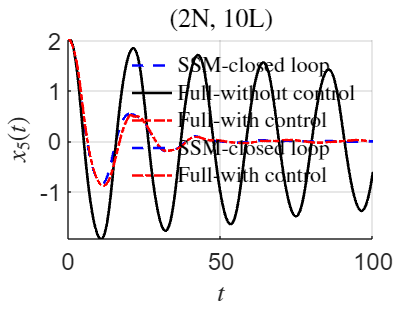

figure; hold on
% plot(traj_open.time, traj_open.zt(1,:),'b-','DisplayName','SSM-open-control');
plot(traj_closed1.time, traj_closed1.zt(2,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot(tfullwo, xfullwo(:,2),'k-','DisplayName', 'Full-without control','LineWidth',2);
plot(tfullwc1, xfullwc1(:,2),'r-.','DisplayName', 'Full-with control','LineWidth',2);

plot(traj_closed2.time, traj_closed2.zt(2,:),'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot(tfullwc2, xfullwc2(:,2),'r-.','DisplayName', 'Full-with control','LineWidth',2);


legend('show','Interpreter',"latex"); legend boxoff
xlabel('$t$','Interpreter',"latex")
zk = strcat('$x_{',num2str(outdof(2)),'}(t)$');
ylabel(zk,'Interpreter','latex');
title('(2N, 10L)','Interpreter',"latex")
set(gca,'FontSize',18);
grid on, axis tight

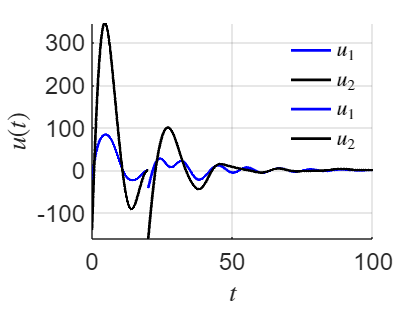

figure; hold on;
plot(traj_closed1.time,traj_closed1.ut(1,:),'b-','DisplayName','SSM-open-control','DisplayName','$u_1$','LineWidth',2);
plot(traj_closed1.time,traj_closed1.ut(2,:),'k-','DisplayName','SSM-closed-control','DisplayName','$u_2$','LineWidth',2);

plot(traj_closed2.time,traj_closed2.ut(1,:),'b-','DisplayName','SSM-open-control','DisplayName','$u_1$','LineWidth',2);
plot(traj_closed2.time,traj_closed2.ut(2,:),'k-','DisplayName','SSM-closed-control','DisplayName','$u_2$','LineWidth',2);

% plot(traj_open.time,traj_open.ut(2,:),'m--','DisplayName','SSM-closed-control','DisplayName','$u_2$');
legend('show','Interpreter','latex'); legend boxoff
xlabel('$t$','Interpreter',"latex")
ylabel('$u(t)$','Interpreter','latex')
set(gca,'FontSize',18); grid on, axis tight

% figure; hold on
% tt = traj_closed.time;
% ep_Vq = traj_closed.zt(1,:) - traj_closed.zt_auto(1,:);
% 
% plot(tt, traj_closed.zt_auto(1,:),'b--','DisplayName','$W(p)$','LineWidth',2);
% plot(tt, ep_Vq,'k-.','DisplayName','$\epsilon Vq$','LineWidth',2);
% 
% legend('show','Interpreter',"latex"); legend boxoff
% xlabel('$t$ ','Interpreter',"latex")
% % zk = strcat('$z_{',num2str(outdof(1)),'}(t)$');
% % ylabel(zk,'Interpreter','latex');
% title('(2N, 10L)','Interpreter',"latex")
% set(gca,'FontSize',18);
% grid on
% % axis tight
% 
% print(gcf, 'Chain_z(t)_Factorization.png', '-dpng','-r300');



% load("tfullwoL.mat","tfullwoL")
% load("xfullwoL.mat","xfullwoL")
% xfullwoL
% figure; hold on
% plot(tfullwo, xfullwo(:,2),'b--','DisplayName', '$\kappa=0$','LineWidth',2);
% 
% plot(tfullwoL, xfullwoL(:,2),'k-','DisplayName', '$\kappa=0.5$','LineWidth',2);
% 
% xlabel('$t$ ','Interpreter',"latex")
% ylabel('$x_5(t)$ ','Interpreter',"latex")
% 
% legend('show','Interpreter',"latex"); legend boxoff
% % title('(2N, 10L)','Interpreter',"latex")
% set(gca,'FontSize',18);
% grid on
% axis tight

## On initial conditions

In previous simulation, we have choosen initial condition such that it is on the SSM we calculated. In practice, the initial condition is off the invariant manifold but the state will converge soon to the invariant manifold. Next, we consider a random initial condition.

**Reduced dynamics simulation - autonomous part**

*Forward simulation of reduced dynamics*

% z0 = [rand(n,1)*0.1; zeros(n,1)];
% tf = 100;
% nsteps = 10000;
% set(DS,'u',[]);

**ROM-based closed loop control**

% traj2_open = LQR_open_loop(DS,z0,'nonlinear',tspan,auData,W_0,modes,1:4,cont);

**ROM-based closed loop control**

% % traj2_closed = LQR_closed_loop(DS,z0,'nonlinear',tspan,auData,W_0,modes,1:10,cont);
% 

#### MT

% traj3 = NotTT_LQR_closed_loop_MT2(DS,z0,'nonlinear',tspan,auData,W_0,modes,5,cont);

#### BT

% % traj4 = LQR_Closed_Loop_BT(DS,z0,'nonlinear',tspan,auData,W_0,modes,cont);

**Full dynamics simulation - without control**

% [tfullwo2, xfullwo2] = time_integration_transient(DS,om,'nCycles',...
%     1, 'nSteps', nsteps,...
%     'integrationMethod','ode45','outdof',outdof,'init',z0);

**Full dynamics simulation - with control**

% om = 2*pi/tf;
% ufun = @(t) transpose(interp1(traj3.time,traj3.ut',t));
% set(DS,'u',ufun);
% [tfullwc2, xfullwc2] = time_integration_transient(DS,om,'nCycles',...
%     1, 'nSteps', nsteps,...
%     'integrationMethod','ode45','outdof',outdof,'init',z0);
% 

**Comparison with full dynamics**

% figure; hold on
% plot(traj2_open.time, traj2_open.zt(1,:),'b-','DisplayName','SSM-open-control');
% % plot(traj2_closed.time, traj2_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
% plot(traj3.time, traj3.zt(1,:),'g--','DisplayName','SSM-closed-control-MT');
% % plot(traj4.time, traj4.zt(1,:),'c--','DisplayName','SSM-closed-control-BT');
% plot(tfullwo2, xfullwo2(:,1),'k-','DisplayName', 'Full-without control');
% plot(tfullwc2, xfullwc2(:,1),'r-.','DisplayName', 'Full-with control');
% legend('show'); legend boxoff
% xlabel('$t$','Interpreter',"latex")
% zk = strcat('$z_{',num2str(outdof(1)),'}(t)$');
% ylabel(zk,'Interpreter','latex');
% title('2D Reduction')
% set(gca,'FontSize',14);
% grid on, axis tight

% figure; hold on;
% plot(traj2_open.time,traj2_open.ut(1,:),'b-','DisplayName','SSM-open-control');
% plot(traj3.time,traj3.ut(1,:),'m--','DisplayName','SSM-closed-control-MT');
% xlabel('$t$','Interpreter',"latex")
% ylabel('$u$','Interpreter','latex')
% set(gca,'FontSize',14); grid on, axis tight